# 034IN -FONDAMENTI DI AUTOMATICA - FUNDAMENTALS OF AUTOMATIC CONTROL 

# FULL WRITTEN EXAMINATION -  A.Y. 2023/2024

**September 16, 2024**

# PART 1 - Problem 2 - State and Output Response using the Control System Toolbox

**Tag List**: `[STANDARD ASSESSMENT] [PARTIAL CREDIT] [CONTROL SYSTEM TOOLBOX]`

Consider the LTI dynamic system described by the following state equations


$$\left\{ \begin{array}{rcl}
\dot{x}_1(t) &=& -2 \,x_1(t) + 16\, u(t)\\
\dot{x}_2(t) &=& -8\, x_1(t) - 24 \, x_2(t) \\
y(t) &=& x_1(t) - 3\,x_2(t)
\end{array} \right.$$


Consider **two** different **scenarios** for the initial state $x(0)$


$$\begin{array}{rclcrcl}
x^{(a)}_{0} &=& \left[ \begin{array}{c} -4 \\ +8 \end{array} \right] & \quad &
x^{(b)}_{0} &=& \left[ \begin{array}{c} 0 \\ +15 \end{array} \right] 
\end{array}$$


In both cases, the input $u(t)$ is as follows:


$$u(t) = \big[16+ cos\left(2.3\,t\right) -4.2 \sin\left(23\,t) \big]\cdot \mathbf{1}(t)$$


As usual, $\mathbf{1}(t)$ denotes the unit step function: $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 1
\end{array} \right.$   $\mathbf{1}(\tau) = \left\{ \begin{array}{rcl}
0 &\longleftrightarrow& \tau <0 \\
1 &\longleftrightarrow& \tau \ge 0
\end{array} \right.$

**Determine** the state response $x(t)$ and the output response $y(t)$ according to: 


$$x(t) = e^{At}x_0+\int_0^{t}\,e^{A(t-\tau)}B u(\tau) \,d\tau $$



$$y(t) = Ce^{At}x_0+\int_0^{t}\,Ce^{A(t-\tau)}B u(\tau) \,d\tau$$


in the time interval 


$$t \in \big[0\,,\; 10\big]$$


## Assignment

Your code shall:

- Create the **numeric** matrices **A, B,** **C **and** D** according to the system description.

- Create two **numeric** array for the possible initial states **x0a** and **x0b**.

- Create an array with time instants in the given interval $[0,\,10]$. Use the function `linspace( )` and create an array with **50000** time instants, named **t**.

- Using the already defined array t, compute **50000** samples of the input function $u(t)$. Assing the result to the **numeric** **array** named **u**.

- **Scenario (a)**: Compute the state and the output response when the initial state is **x0a** and the input is **u**. Use the function `lsim( )` ONLY. Assign the resulting state and output responses to the variables **x_a** and **y_a**.

- **Scenario (b)**: Compute the state and the output response when the initial state is **x0b** and the input is **u**. Use the function `lsim( )` ONLY. Assign the resulting state and output responses to the variables **x_b** and **y_b**.

## Solution

Compare with Grader-State & Output Trajectory of ... - Problem 5

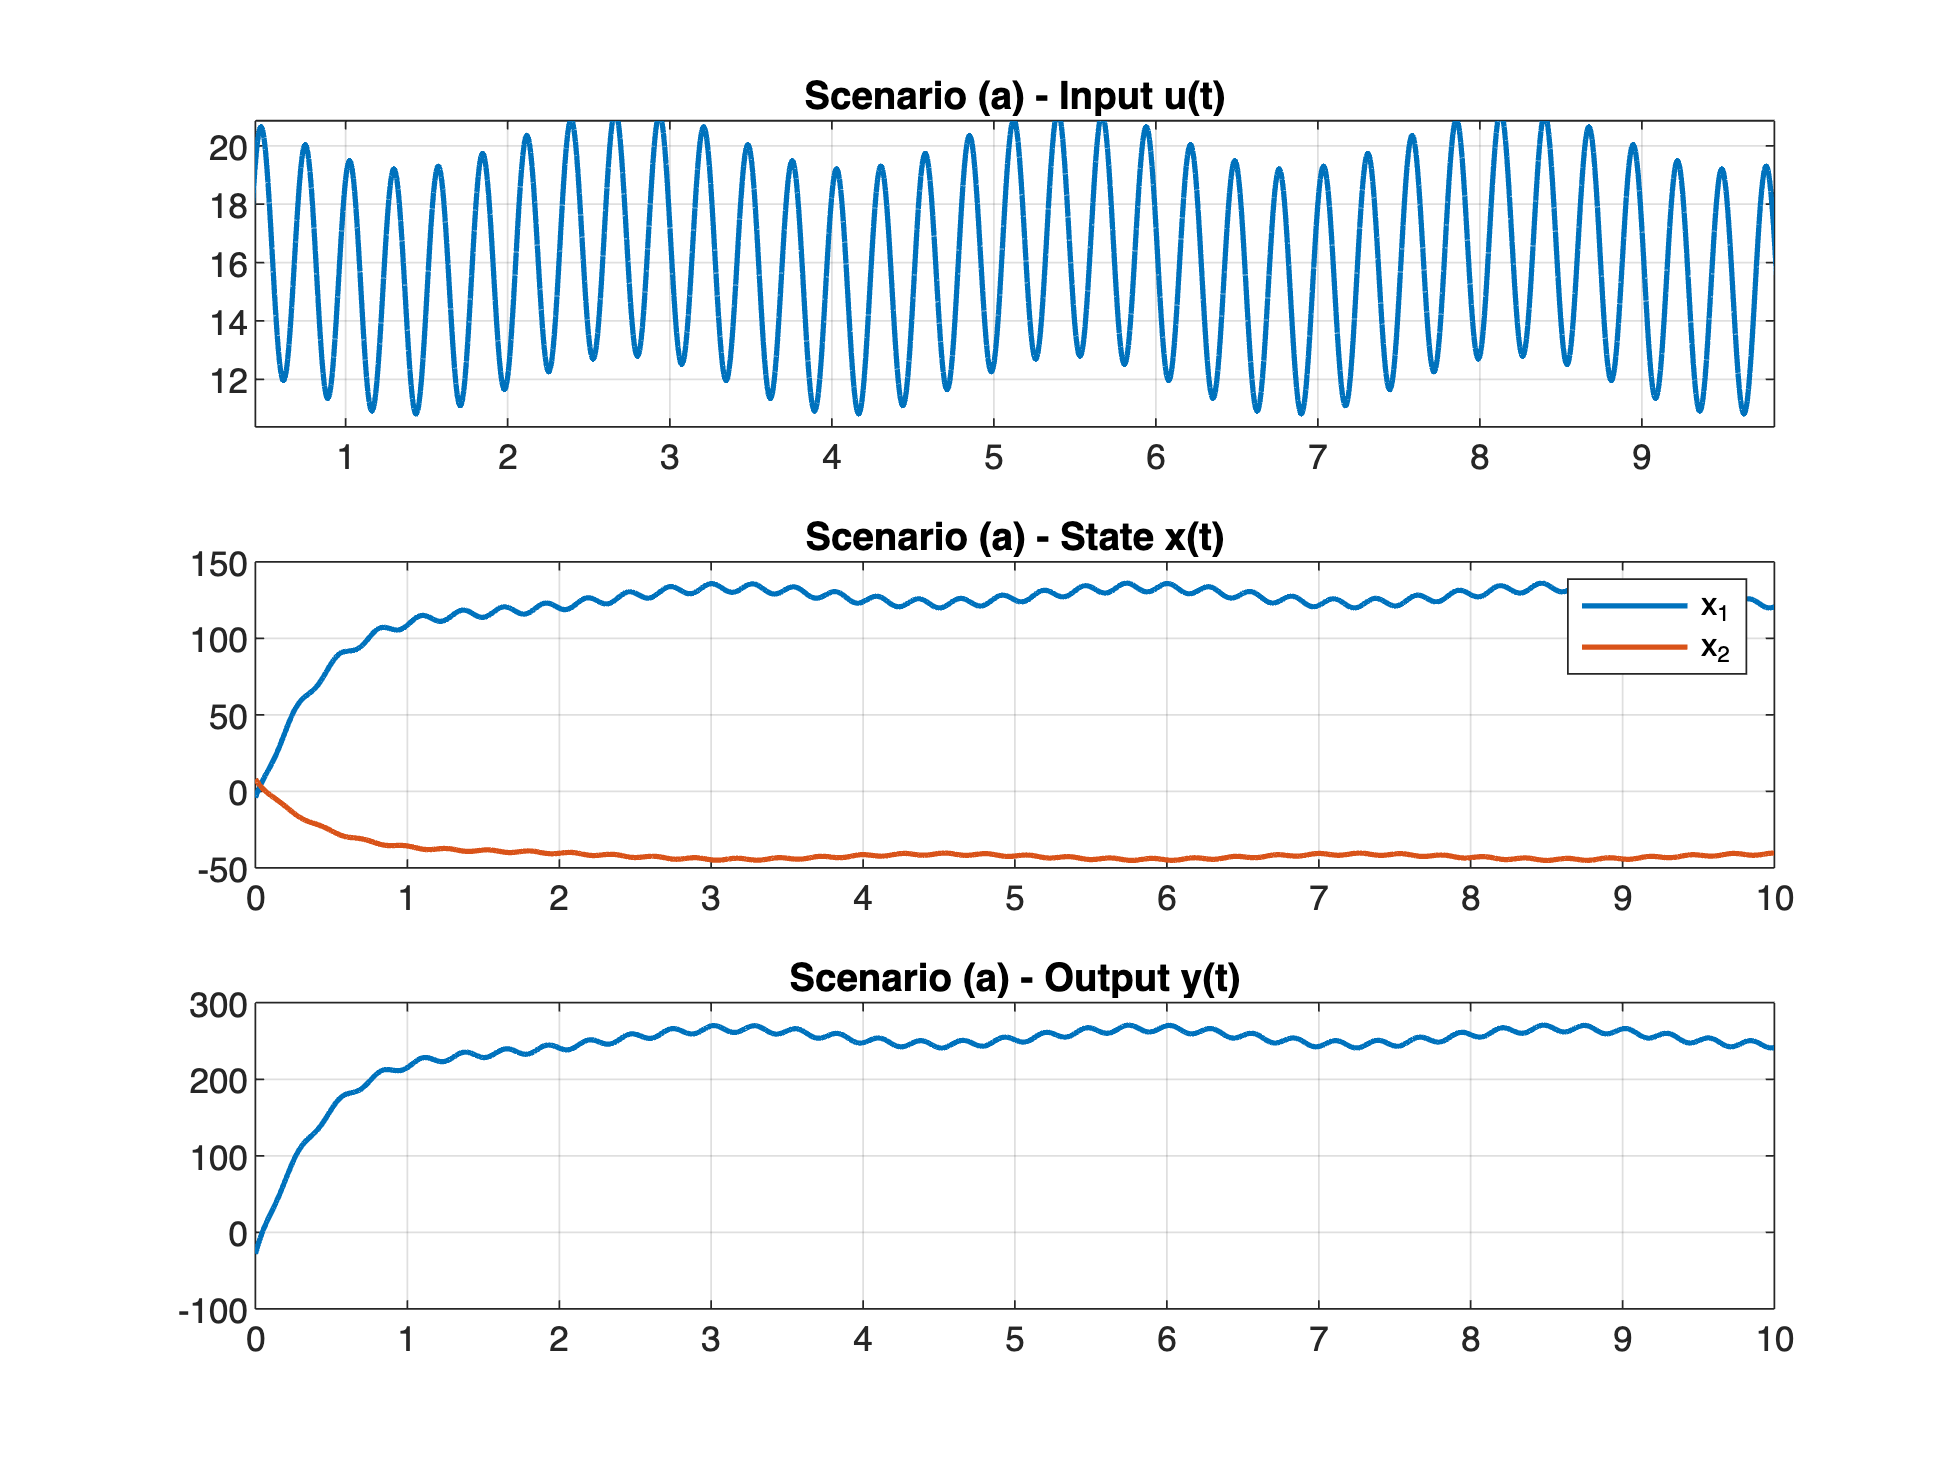

clear

% system matrices
A = [       -2         0;
            -8       -24];
B = [16 ; 0];
C = [1   -3]; 
D = 0;

% time array
t = linspace(0, 10, 50000);

% input array
 u = (16+cos(2.3*t)-4.2*sin(23*t)).*heaviside(t); 

% LTI system
LTISYS = ss(A,B,C,D);

% initial state
x0a = [-4; +8]; x0b = [0; +15];

% scenario (a)
[y_a, ~, x_a] = lsim(LTISYS,u,t, x0a );

% plot the results -- NOT REQUIRED
figure;
subplot(3,1,1);
plot(t,u, 'linewidth', 1.5);
title('Scenario (a) - Input u(t)')
grid on; zoom on
subplot(3,1,2);
plot(t, x_a, "LineWidth", 1.5);
title('Scenario (a) - State x(t)')
legend('x_1', 'x_2')
grid on; zoom on
subplot(3,1,3);
plot(t, y_a, "LineWidth", 1.5);
title('Scenario (a) - Output y(t)')
grid on; zoom on

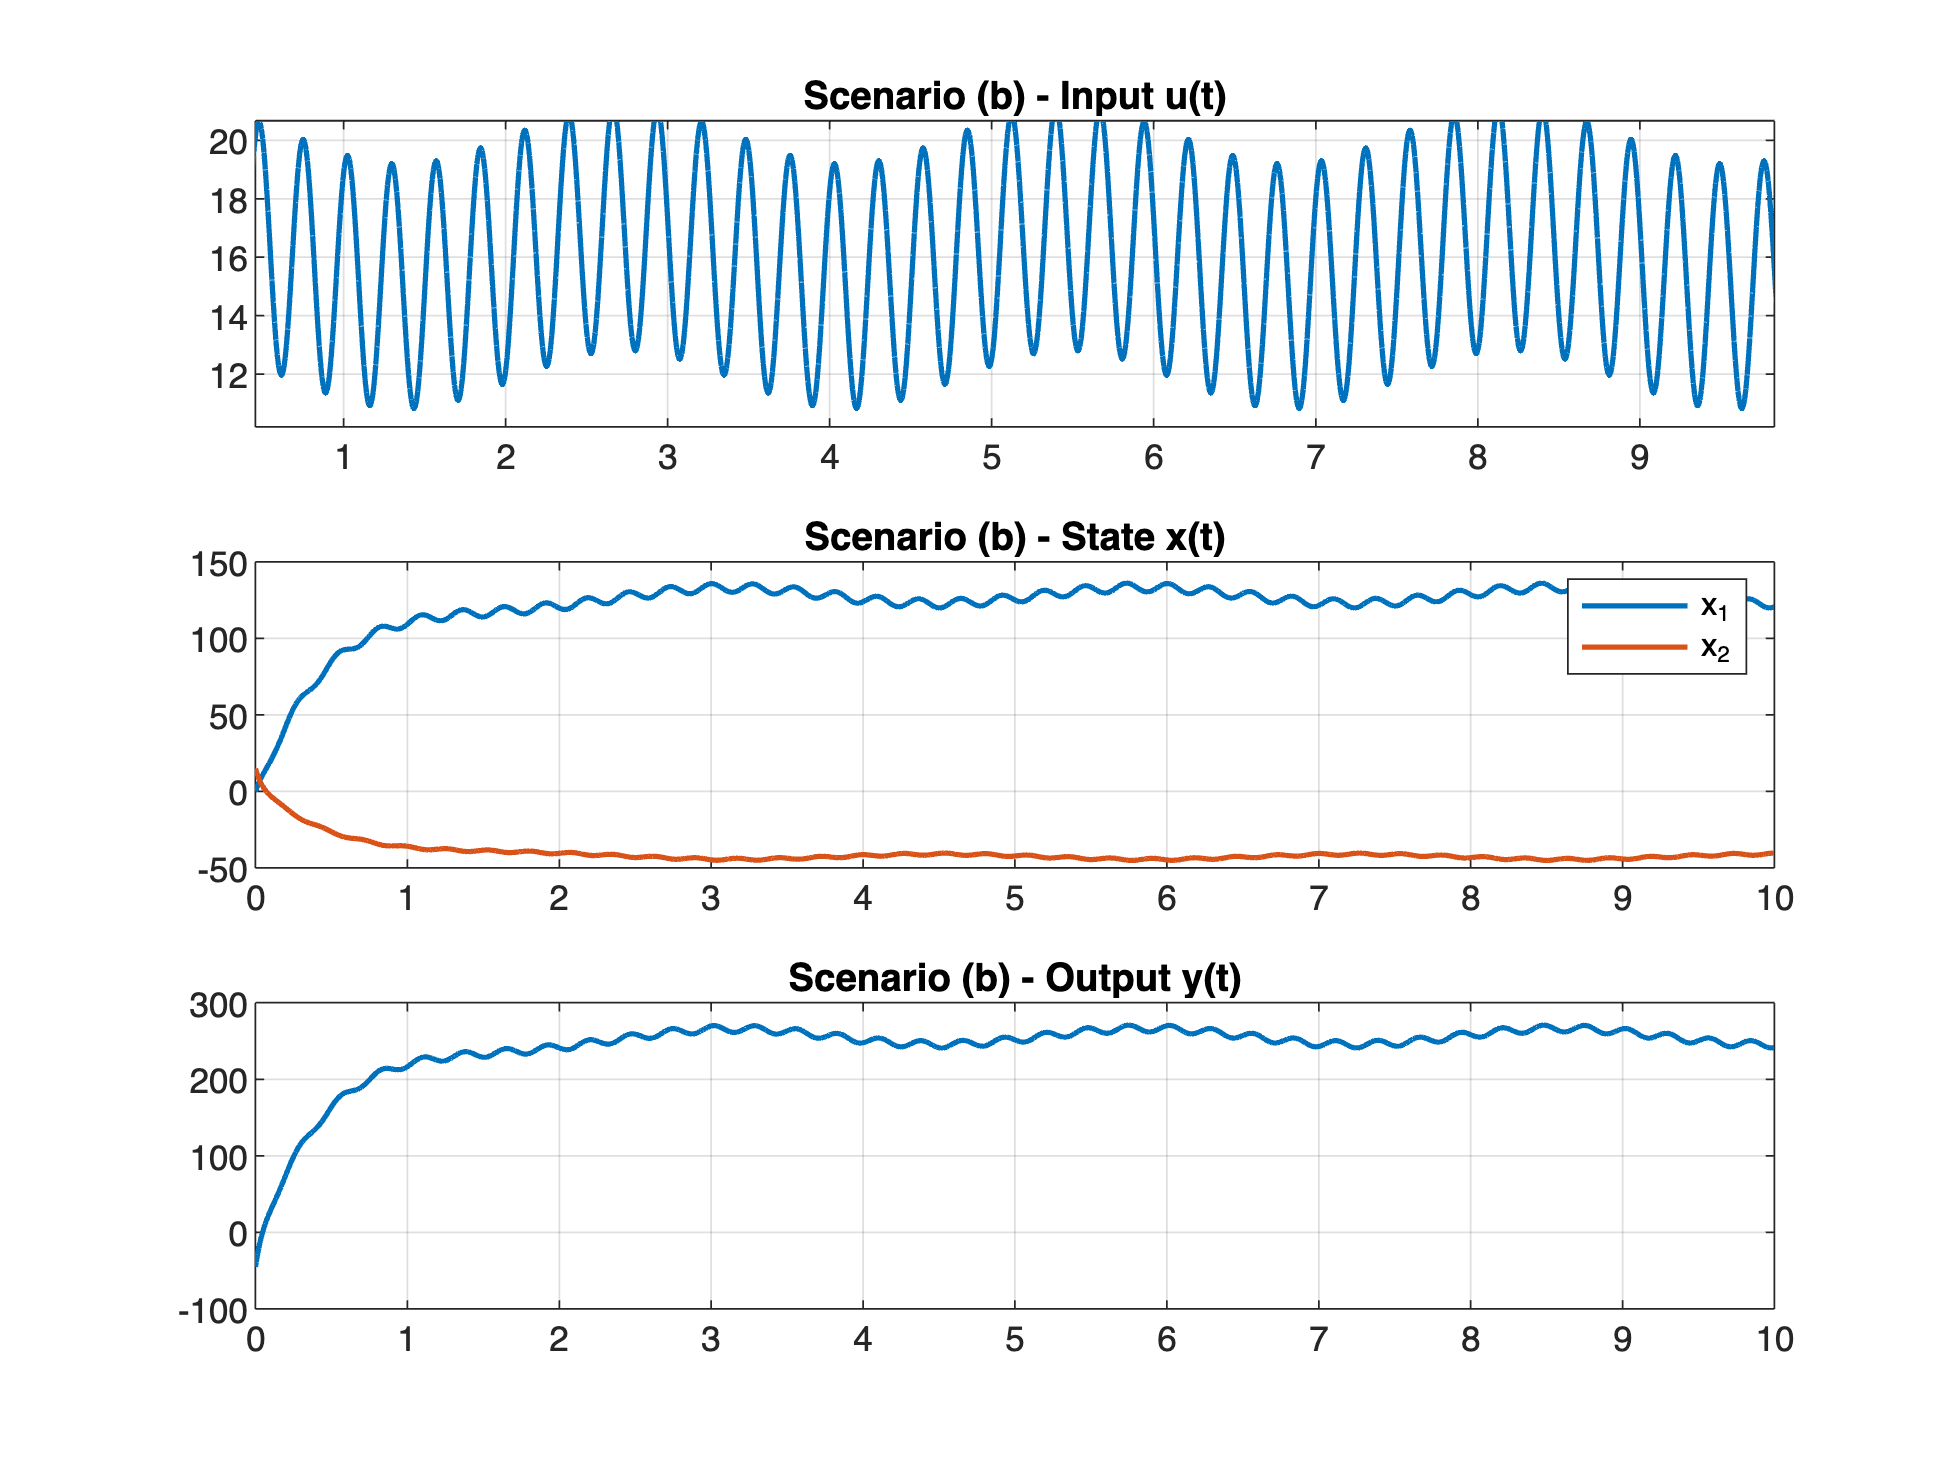



% scenario (b)
[y_b, ~, x_b] = lsim(LTISYS,u,t, x0b );

% plot the results
figure;
subplot(3,1,1);
plot(t,u, 'linewidth', 1.5);
title('Scenario (b) - Input u(t)')
grid on; zoom on
subplot(3,1,2);
plot(t, x_b, "LineWidth", 1.5);
title('Scenario (b) - State x(t)')
legend('x_1', 'x_2')
grid on; zoom on
subplot(3,1,3);
plot(t, y_b, "LineWidth", 1.5);
title('Scenario (b) - Output y(t)')
grid on; zoom on